# Rad229 - Lecture 3:  Block Equation Matrix Simulations

## lec3_01.m:  Use plotm.m to Plot Magnetization

Here we give 2 examples to show the plotm.m function, which we hope is useful to you.  First, we just define 3 magnetization vectors and plot them.  Which color corresponds to which?  Second, we generate "dephased" magnetization - spins that have different phase angles.  

*Note that if you download and install arrow3D your plots will look nicer!  You can google "arrow3D matlab" or get it here:  https://www.mathworks.com/matlabcentral/fileexchange/71994-arrow-3d*

% Lecture 3, Example 01
% 
% Plot some mangetization vectors using plotm.m
%
% Simple 3x1 vectors - ; ends a row in Matlab:
M1 = [0; 0; 1];         % "Equilibrim" magnetization along Mz
M2 = [1; 0; 0];         % Magnetization long Mx
M3 = [0; 0.5; 0];       % Shorter magnetization along My

% plotm.m can plot a (3xN) array of spins all at once:
figure(1); disp('Example of 3 Spins');

Example of 3 Spins


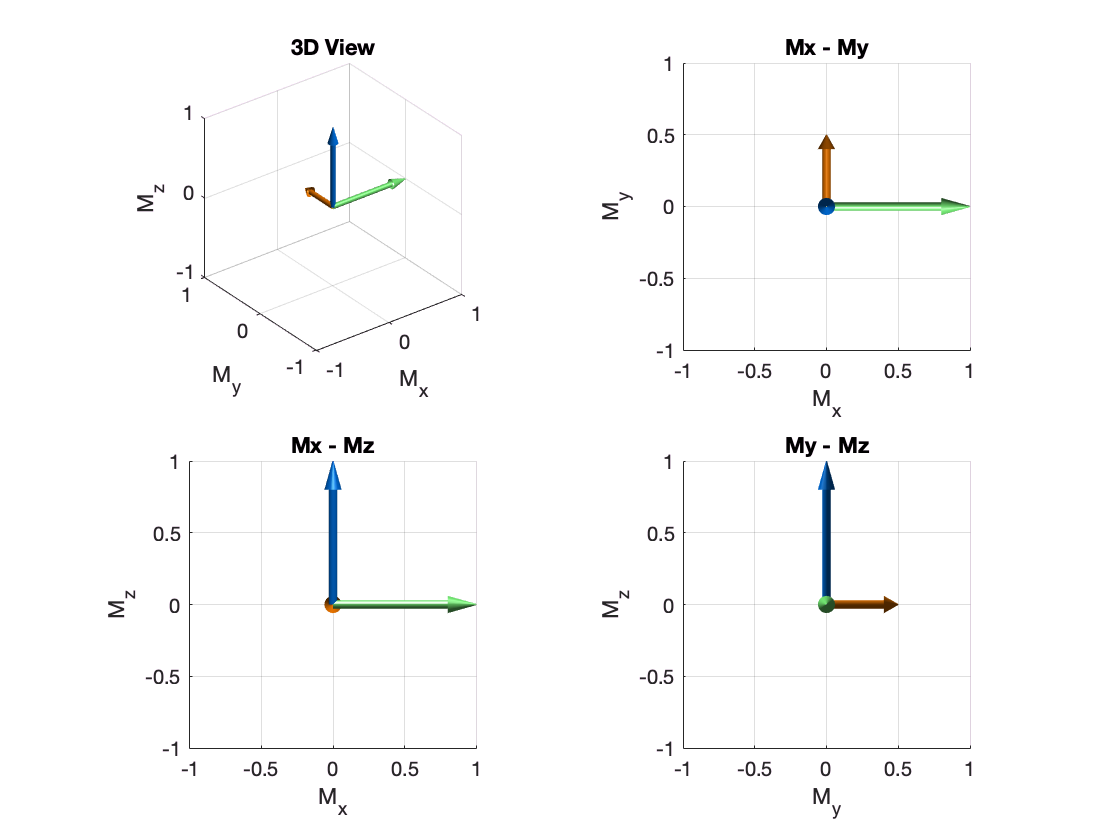

plotm([M1 M2 M3]);      % Notice we concatenate them horizontally.

%
% Which color corresponds to which M vector?
%
% You can also plot some dephased spins:
%pa
figure(2); disp('Dephased Spins');

Dephased Spins


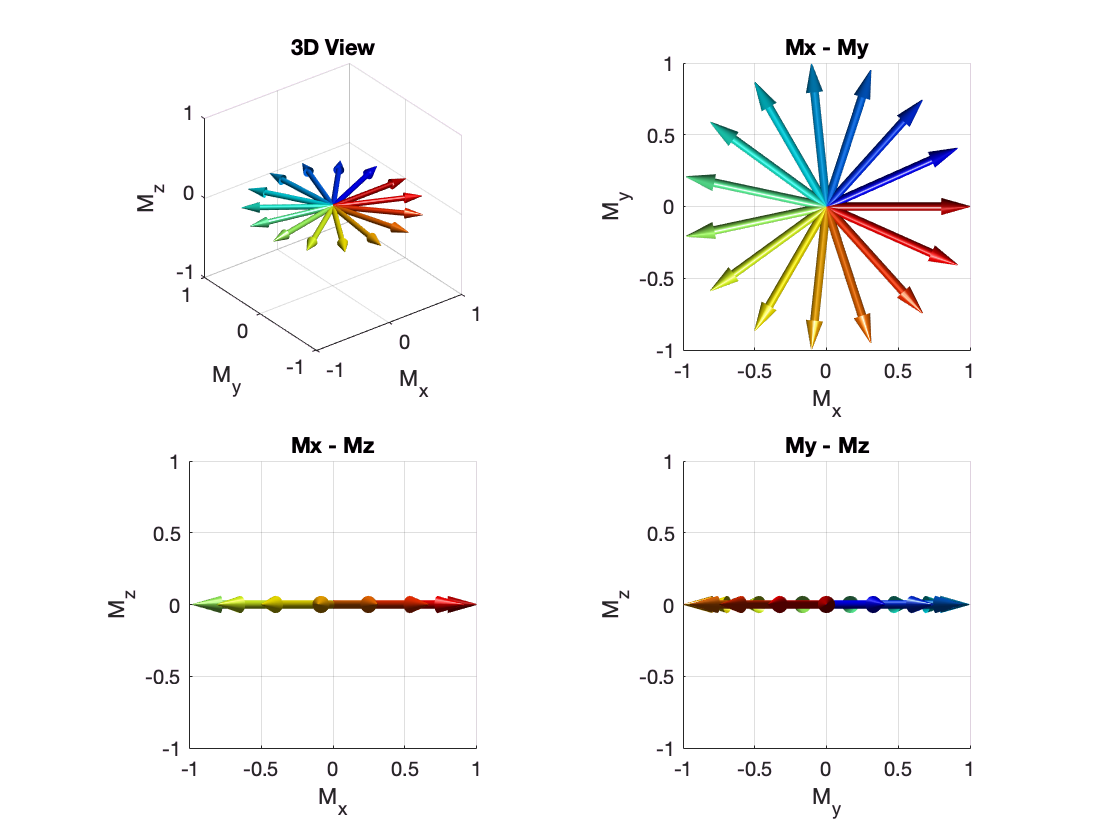

x = [0:15];
M = [cos(2*pi*x/15); sin(2*pi*x/15); 0*x];
plotm(M);

Question 1:  What color corresponds to M1, M2 and M3?

Optional:  Have a look at plotm.m and the function it calls - showspins.m.

## lec3_02.m:  Animate Excitation and Precession

Here we will use the yrot.m and zrot.m functions to excite (nutate) and simulate precession.

% Lecture 3, Example 02
%
% Use the rotation functions to animate excitation, precession
%
M = [0;0;1];    % Equilibrium
Ne = 10;                % Frames - excitation
Np = 50;                % Frames - precession
Nrot = 1;               % cycles
Ry = yrot(-90/Ne);      % Rotation about My
Rz = zrot(360/Nrot/Np); % Rotation about Mz

figure(3); disp('Excitation/Rotation');

Excitation/Rotation


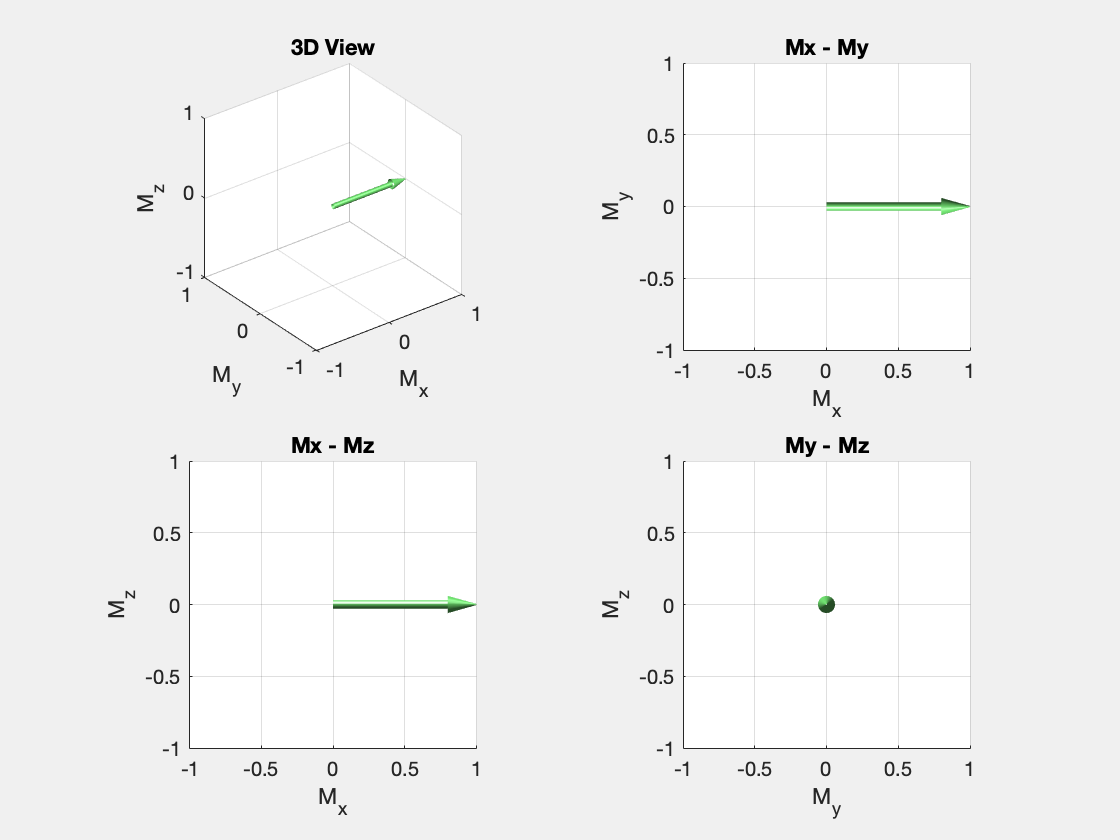

plotm(M);
for n=1:Ne;
  M=Ry*M; plotm(M);     % Rotate and plot
  drawnow;
end;

for n=1:Np;
  M=Rz*M; plotm(M);     % Rotate and plot
  drawnow;
end;


% Exercise:  Add relaxation so that the spins return to Mz after 5 rotations